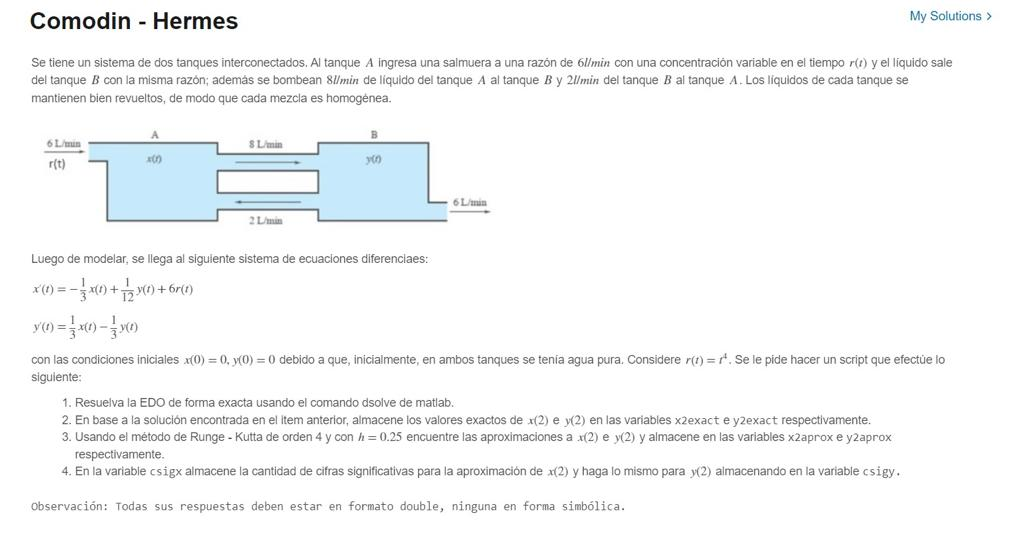

syms x(t) y(t) t

x0 = 0; y0 = 0

y0 =      0



f = @(t,x,y) (-1/3*x + 1/12*y + 6*t^4)

f = function_handle with value:
    @(t,x,y)(-1/3*x+1/12*y+6*t^4)


g = @(t,x,y) (1/3*x - 1/3*y)

g = function_handle with value:
    @(t,x,y)(1/3*x-1/3*y)



%x(t) = dsolve(diff(f, t) == (-1/3*x + 1/12*y + 6*t^4), x(0) ==  )



%x(t) = dsolve(Dx = -1/3 *x + 1/12 *y + 6t^4,)


f=@(t,x,y)(y)

f = function_handle with value:
    @(t,x,y)(y)


g=@(t,x,y)(-2*y-x)

g = function_handle with value:
    @(t,x,y)(-2*y-x)


a=-3;b=6;x0=1;y0=10;n=20;


syms y(t);

Dy = diff(y)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$


D2y = diff(y,2)

$$D2y(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$


S = dsolve(D2y== -2*Dy-y, y(a)==x0, Dy(a)==y0)

$$S = {\mathrm{e}}^{-t}\,{\mathrm{e}}^{-3}\,\left(11\,t+34\right)$$

exacta = matlabFunction(S)

exacta = function_handle with value:
    @(t)exp(-t).*exp(-3.0).*(t.*1.1e+1+3.4e+1)


tt = a:0.001:b

tt =   -3.000000000000000  -2.999000000000000  -2.998000000000000  -2.997000000000000  -2.996000000000000  -2.995000000000000  -2.994000000000000  -2.993000000000000  -2.992000000000000  -2.991000000000000  -2.990000000000000  -2.989000000000000  -2.988000000000000  -2.987000000000000  -2.986000000000000  -2.985000000000000  -2.984000000000000  -2.983000000000000  -2.982000000000000  -2.981000000000000  -2.980000000000000  -2.979000000000000  -2.978000000000000  -2.977000000000000  -2.976000000000000  -2.975000000000000  -2.974000000000000  -2.973000000000000  -2.972000000000000  -2.971000000000000  -2.970000000000000  -2.969000000000000  -2.968000000000000  -2.967000000000000  -2.966000000000000  -2.965000000000000  -2.964000000000000  -2.963000000000000  -2.962000000000000  -2.961000000000000  -2.960000000000000  -2.959000000000000  -2.958000000000000  -2.957000000000000  -2.956000000000000  -2.955000000000000  -2.954000000000000  -2.953000000000000  -2.952000000000000  -2.9510000000

solex = exacta(tt)

solex =    1.000000000000000   1.009989505331538   1.019958042638013   1.029905643854985   1.039832340875124   1.049738165548280   1.059623149681491   1.069487325039092   1.079330723342723   1.089153376271396   1.098955315461576   1.108736572507190   1.118497178959703   1.128237166328190   1.137956566079339   1.147655409637567   1.157333728385017   1.166991553661636   1.176628916765245   1.186245848951555   1.195842381434240   1.205418545385006   1.214974371933601   1.224509892167916   1.234025137134000   1.243520137836123   1.252994925236853   1.262449530257069   1.271883983776031   1.281298316631455   1.290692559619514   1.300066743494952   1.309420898971079   1.318755056719850   1.328069247371930   1.337363501516734   1.346637849702440   1.355892322436115   1.365126950183720   1.374341763370160   1.383536792379343   1.392712067554257   1.401867619196969   1.411003477568735   1.420119672890003   1.429216235340482   1.438293195059217   1.447350582144596   1.456388426654426   1.4654067

%[z]=RK2sistemas(f,g,a,b,x0,y0,n);
%plot(z(:,1),z(:,2),'b',z(:,1),z(:,3),'g',tt,solex,'r')


format long
%1
E = 30000

E =        30000


I = 800

I =    800


P = 1

P =      1


L = 10

L =     10



syms y(t)

Dy = diff(y)

$$Dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

D2y = diff(y,2)

$$D2y(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)$$

S = dsolve(D2y==-P*(L-t)/(E*I),y(0)==0,Dy(0)==0)

$$S = -\frac{t\,\left(30\,t-t^{2}\right)}{144000000}$$

t = [0:1:10]';
yexac = double(subs(S,t))

yexac = 1.0e-04 *

                   0
  -0.002013888888889
  -0.007777777777778
  -0.016875000000000
  -0.028888888888889
  -0.043402777777778
  -0.060000000000000
  -0.078263888888889
  -0.097777777777778
  -0.118125000000000



%2
y_rk4=[yexac(1);yexac(3);yexac(5);yexac(7);yexac(9);yexac(11)]

y_rk4 = 1.0e-04 *

                   0
  -0.007777777777778
  -0.028888888888889
  -0.060000000000000
  -0.097777777777778
  -0.138888888888889



%3
y_rk2=[yexac(1);yexac(3);yexac(5);yexac(7);yexac(9);yexac(11)]

y_rk2 = 1.0e-04 *

                   0
  -0.007777777777778
  -0.028888888888889
  -0.060000000000000
  -0.097777777777778
  -0.138888888888889



%4
MAE=[yexac(1);yexac(3);yexac(5);yexac(7);yexac(9);yexac(11)]

MAE = 1.0e-04 *

                   0
  -0.007777777777778
  -0.028888888888889
  -0.060000000000000
  -0.097777777777778
  -0.138888888888889



syms y(x) x

y(x) = dsolve(diff(y,x)==-2*x^3+12*x^2-20*x+8.5,y(0)==1)

$$y(x) = -\frac{x^{4}}{2}+4\,x^{3}-10\,x^{2}+\frac{17\,x}{2}+1$$

solexac=matlabFunction(y(x))

solexac = function_handle with value:
    @(x)x.*(1.7e+1./2.0)-x.^2.*1.0e+1+x.^3.*4.0-x.^4./2.0+1.0


a=0; b=1; y0=1;
f=@(x,y) -2.*x.^3 +12.*x.^2-20.*x+8.5;

% No usar matlab function porque no reconoce la variable y 
[k,l]=euler(f,a,b,y0,0.5)

k =          0    1.0000
    0.5000    5.2500
    1.0000    5.8750


l =     1.0000
    5.2500
    5.8750


[m ,n]=rk2(f,a,b,y0,0.5)  %El metodo de runge kutta es mas exacato 

m =          0    1.0000
    0.5000    3.4375
    1.0000    3.3750


n =     1.0000
    3.4375
    3.3750



%sol = dsolve(diff(x,t) == 2*x + 4*y,diff(y,t) == -x + 6*y,x(0)==-1,y(0)==6);
%solx = matlabFunction(sol.x);
%soly = matlabFunction(sol.y);
%[xrk2, yrk2] = rk2_sist(f,g,a,b,x0,y0,h);
syms y(t) t
v=60

v = 60

y(t)=dsolve(diff(y,t)== t*exp(-(4/3))*80-(y/v)*80,y(0)==0.03)

$$y(t) = \frac{71228158379634975\,t}{4503599627370496}+\frac{5355622677354734613\,{\mathrm{e}}^{-\frac{4\,t}{3}}}{450359962737049600}-\frac{213684475138904925}{18014398509481984}$$

solexacta=matlabFunction(y(t))

solexacta = function_handle with value:
    @(t)t.*1.581582828694361e+1+exp(t.*(-4.0./3.0)).*1.18918712152077e+1-1.18618712152077e+1


solexacta(1.2392)

ans = 10.0158

format long
%variables I_exac  I_euler   I_ptomedio  I_rk4  Ea 
%I_exac (vector columna)
%I_euler (vector columna)
%I_ptomedio (vector columna)
%I_rk4 (vector columna)
%Ea (matriz)

R = 1.5; L = 1;
a = 0; b = 5; h = 0.2; I_0 = 0.5;
ts = (a:h:b)'

ts =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000
   1.200000000000000
   1.400000000000000
   1.600000000000000
   1.800000000000000



f = @(I,t)((-R/L)*(I - I^3))

f = function_handle with value:
    @(I,t)((-R/L)*(I-I^3))



% item 1
syms I(t) t
I(t) = dsolve(diff(I,t) == (-R/L)*(I - I^3), I(0) == I_0)

$$I(t) = \sqrt{\frac{1}{{\mathrm{e}}^{3\,t+\log\left(3\right)}+1}}$$

I = matlabFunction(I(t))

I = function_handle with value:
    @(t)sqrt(1.0./(exp(t.*3.0+log(3.0))+1.0))



I_exac = I(ts)

I_exac =    0.500000000000000
   0.393251312874718
   0.302056213140026
   0.228521782880838
   0.171323498493417
   0.127768418103826
   0.095003695831437
   0.070524212983050
   0.052304341968762
   0.038771945742969



% item 2z
z = euler(f,a,b,I_0,h);

I_euler = z(:,1:2)

I_euler = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.005000000000000
   0.004000000000000   0.004424000000000
   0.006000000000000   0.003416000000000
   0.008000000000000   0.002264000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.001400000000000
   0.014000000000000   0.002984000000000
   0.016000000000000   0.007016000000000
   0.018000000000000   0.014504000000000



% item 3
z = rk2(f,a,b,I_0,h);

I_ptomedio = z(:,1:2)

I_ptomedio = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.004712000000000
   0.004000000000000   0.003920000000000
   0.006000000000000   0.002840000000000
   0.008000000000000   0.001832000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.002192000000000
   0.014000000000000   0.005000000000000
   0.016000000000000   0.010760000000000
   0.018000000000000   0.020552000000000



% item 4
z = rk4(f,a,b,I_0,h);

I_rk4 = z(:,1:2)

Index in position 2 exceeds array bounds. Index must not exceed 1.




% item 5
ea1 = abs(I_exac - I_euler);

ea2 = abs(I_exac - I_ptomedio);

ea3 = abs(I_exac - I_rk4);

Ea = [ea1 ea2 ea3]

tt = a:0.01:b;

I_exac = I_exac(tt)

plot(tt, I_exac,'r', I_euler(:,1), I_euler(:,2),'b', I_ptomedio(:,1), I_ptomedio(:,2),'g', I_rk4(:,1), I_rk4(:,2), 'black')

FUNCIONES

Solo para resolver ecuaciones diferenciales.

function [z, y1] = euler(f,a,b,y0,h)
    x = a:h:b; x=x';
    y1(1) = y0;
    z = [x(1) y1(1)];
    for i = 1:length(x)-1
        y1(i+1,1) = y0 + h*f(x(i),y0);
        y0 = y1(i+1,1);
        z = [z; x(i+1) y1(i+1,1)];
    end
end

function [z, y1] = rk2(f,a,b,y0,h)
% Este es el caso de runge kutta segundo orden metodo de heun
    x = a:h:b; x = x';
    y1(1) = y0;
    z = [x(1) y1(1)];
    for i = 1:length(x)-1
        k1 = f(x(i),y0);
        k2 = f(x(i)+h,y0 + k1*h);
        %           yi+ h*(a1*k1+02*k2)
        y1(i+1,1) = y0 + h*(0.5*k1 + 0.5*k2);
        y0 = y1(i+1,1);
        z = [z; x(i+1) y1(i+1,1)];

        % La segunda columna es lo que se quiere hallar es decir la
        % solucion de la edo 
    end
end

function yrk4 = rk4(f,a,b,y0,h)
%Runge Kutta orden 4 para solo una ecuacion diferencial   
    x = a:h:b; x = x';
    y1(1) = y0;
    for i = 1:length(x)-1
        k1 = f(x(i),y0);
        k2 = f(x(i+1),y0 + 0.5*k1*h);
        k3 = f(x(i+1),y0 + 0.5*k2*h);
        k4 = f(x(i+1),y0 + k3*h);
        y1(i+1,1) = y0 + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
        y0 = y1(i+1,1);
    end
    yrk4 = y1;
end

Para sistema de ecuaciones difrenciales

function [xrk2, yrk2] = rk2_sist(f,g,a,b,x0,y0,h)
%Runge kutta para sisitema  de ecuaciones recibe ambas funciones y ambas condiciones iniciales
%Lo demas mantiene cosntate 
tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        k2x = f(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        k2y = g(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        x1(i+1,1) = x0 + h*(0.5*k1x + 0.5*k2x);
        y1(i+1,1) = y0 + h*(0.5*k1y + 0.5*k2y);
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xrk2 = x1;
    yrk2 = y1;
end

function [xsol, ysol] = rk4_sist(f,g,a,b,x0,y0,h)
    tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        k2x = f(tt(i) + 0.5*h,x0 + 0.5*h*k1x,y0 + 0.5*h*k1y);
        k2y = g(tt(i) + 0.5*h,x0 + 0.5*h*k1x,y0 + 0.5*h*k1y);
        k3x = f(tt(i) + 0.5*h,x0 + 0.5*h*k2x,y0 + 0.5*h*k2y);
        k3y = g(tt(i) + 0.5*h,x0 + 0.5*h*k2x,y0 + 0.5*h*k2y);
        k4x = f(tt(i) + h,x0 + h*k3x,y0 + h*k3y);
        k4y = g(tt(i) + h,x0 + h*k3x,y0 + h*k3y);
        x1(i+1,1) = x0 + (h/6)*(k1x + 2*k2x + 2*k3x + k4x);
        y1(i+1,1) = y0 + (h/6)*(k1y + 2*k2y + 2*k3y + k4y);
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xsol = x1;
    ysol = y1;
end